%% PrograMMation du siMulateur pour le Bureau d'Etude de DSAS 
%           Maintien a poste autonoMe d'un satellite
% 
%       Fils Elie Boungoueres 
%       Khabane Niang 
%       Master ISC - AM2AS
% 
%       Encadrant : Christophe Fargues
%       Le 12/01/2024
clear, close all; clc;

## Chargement des donnees et parametres orbitaux

initialisation_a_distribuer; 

## Choix du correcteur / ou sans 

% Mettre a 1 le correcteur que vous voulez utiliser durant la simulation 
nocoorK0 =1; 
corrK1 =0;
corrK2 =0;
corrKp =0;

## Matrices d'etat du systeme et linearisation autour d'un point d'equilibre 

% declaration des variables syMboliques 
syms xM yM zM xdotM ydotM zdotM xddotM yddotM zddotM real 
syms ux uy uz real 
syms ebs rad rau ebs_dot rad_dot rau_dot u_ebs u_rad u_rau real

a = 7068e3;
n= sqrt(mu/a^3);

x1 = ebs;
x2 =rad; 
x3 =rau;

x4 = ebs_dot;
x5 = rad_dot; 
x6 = rau_dot;

ebs_ddot = 2*n*rad_dot + 3*n^2*ebs + u_ebs;
rad_ddot = -2*n*ebs_dot + u_rad;
rau_ddot = u_rau - n^2*rau;

X=[x1;x2;x3;x4;x5;x6];

f = [ebs_dot
    rad_dot
    rau_dot
    ebs_ddot
    rad_ddot
    rau_ddot];

u =[u_ebs
    u_rad 
    u_rau];
g = X;
%% Methode Jacobian
A=jacobian(f,X); 
B=jacobian(f,u); 
C=jacobian(g,X); 
D=jacobian(g,u);

ebs= 0; rad= 0; rau= 0;
% ebs_dot= 0; rad_dot= 0; rau_dot= 0;

A=eval(A); 
B=eval(B);
C=eval(C);
D=eval(D);
%% Correcteur LQR 
K1=lqr(A,B,eye(6),1e12*eye(3)); disp(K1);

    0.0000   -0.0000    0.0000    0.0018    0.0008    0.0000
    0.0000    0.0000    0.0000    0.0008    0.0017    0.0000
   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0009



K2=lqr(A,B,eye(6),1e14*eye(3)); disp(K2); 

    0.0000   -0.0000    0.0000    0.0002    0.0003    0.0000
    0.0000   -0.0000    0.0000    0.0003    0.0010   -0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001



% Attention au signe - dans la boucle de retroaction 
% car ceci entraine une instabilite du systeme  

## Definition des nouvelles matrices Ap et Bp pour un meileur correcteur 

Ap=[A,zeros(6,3);
    eye(3),zeros(3,6)]; 
Bp=[B;zeros(3,3)]; 
Kp=lqr(Ap,Bp,eye(9),1e14*eye(3));

## Simulation sous simulinnk

t_final = 6000;         % temps/Periode de simulation 
% open('simulik_DSAS_validation.slx');
if nocoorK0 == 1
    Ki = zeros(3,6); 
    sim('simulik_DSAS_validation.slx'); 
end


if corrK1 == 1
    Ki = K1; 
    sim('simulik_DSAS_validation.slx'); 
end

if corrK2 == 1
    Ki = K2; 
    sim('simulik_DSAS_validation.slx'); 
end 

if corrKp == 1
    sim('sch_2.slx'); 
end 

## Traces des simulations

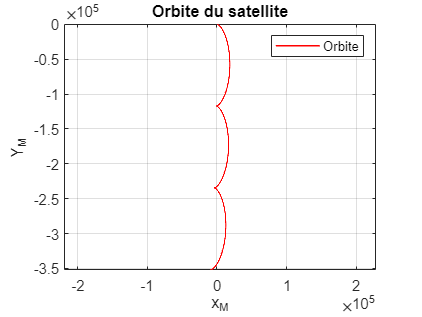

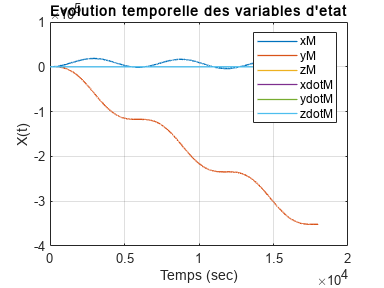

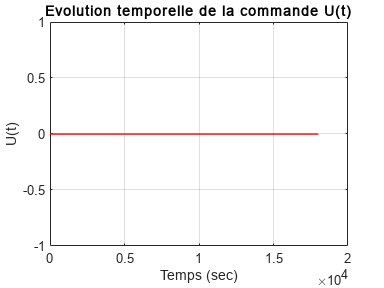

if (nocoorK0 ==1)||(corrK1 ==1)||(corrK2 ==1)||(corrKp ==1)
    squeeze(x);
    squeeze(dtX); 
    
    figure(1); 
    plot(x(1,:),x(2,:),'r','LineWidth',1); grid; 
    title('Orbite du satellite'); xlabel('x_M'),ylabel('Y_M'); axis equal;
    legend('Orbite')
    
    figure, plot(t,x(:,:),"LineWidth",1), grid on; 
    xlabel('Temps (sec)'), ylabel('X(t)')
    title('Evolution temporelle des variables d''etat')
    legend('xM','yM','zM','xdotM','ydotM','zdotM') 

    figure, plot(t,U(:,:),'r','LineWidth',1);grid; 
    xlabel('Temps (sec)'), ylabel('U(t)')
    title('Evolution temporelle de la commande U(t)'); 
    
    if corrKp == 1
        figure(5) 
        plot(t,dtX(:,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title(''); xlabel('t en secondes'),ylabel('f_J2'); axis equal;
        % % legend('')
    
        figure(6) 
        plot(t,f_J2(:,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title(''); xlabel('t en secondes'),ylabel('dtX'); axis equal;
        % % legend('')
    
        figure(7) 
        plot(t,f_atom(:,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title(''); xlabel('t en secondes'),ylabel('f_atom'); axis equal;
        % % legend('')
    
        figure,
        plot(t,xp(1:6,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title('Evolution temporelle du nouveau vecteur d''etat '); xlabel('t en secondes'),ylabel('xp1'); axis equal;
        % % legend('')
    
        figure, 
        plot(t,xp(7,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title('Evolution temporelle du nouveau vecteur d''etat '); xlabel('t en secondes'),ylabel('xp2'); axis equal;
        % % legend('')
        figure, 
        plot(t,xp(8,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title('Evolution temporelle du nouveau vecteur d''etat '); xlabel('t en secondes'),ylabel('xp3'); axis equal;
        % % legend('')
        figure, 
        plot(t,xp(9,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title('Evolution temporelle du nouveau vecteur d''etat '); xlabel('t en secondes'),ylabel('xp'); axis equal;
        % % legend('')
        figure, 
        plot(t,U(:,:)) ; grid;        % car il est renvoye sous 3 dimensions  
        title('Evolution temporelle de l''energie de la commande'); xlabel('t en secondes'),ylabel('Commande U'); axis equal;
        % % legend('')
    end 
end